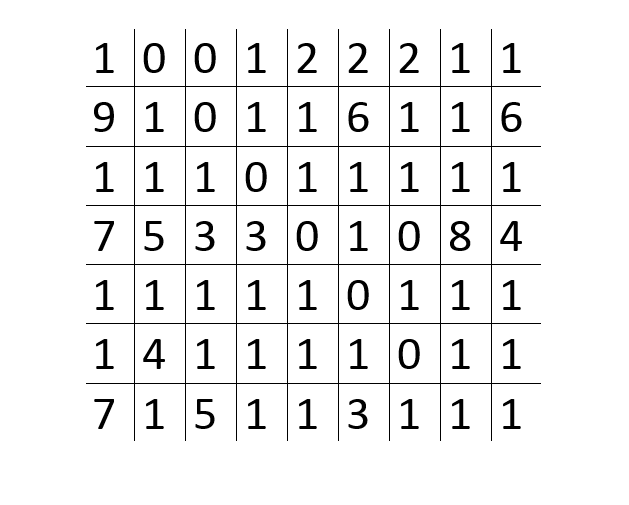

I = imread('puzz11.png');
%I = rgb2gray(I);
%https://www.mathworks.com/help/vision/ref/ocr.html#bt79su1
%https://www.mathworks.com/help/vision/examples/recognize-text-using-optical-character-recognition-ocr.html
figure;
imshow(I)


% Run OCR on the image
results = ocr(I);

results.Text

ans =     '100122211
     910116116
     
     111011111
     753301084
     111110111
     141111011
     715113111
     
     '



% 
% 
% 
% % Set 'TextLayout' to 'Block' to instruct ocr to assume the image
% % contains just one block of text.
% results = ocr(I, 'CharacterSet','0123456789');
% 
% results.Text

ans =     '100122211
     910116116
     
     111011111
     753301084
     111110111
     141111011
     715113111
     
     '


% 
% BW = imbinarize(I);
% results = ocr(BW, 'CharacterSet','0123456789');
% 
% results.Text

ans =     '100122211
     910116116
     
     111011111
     753301084
     111110111
     141111011
     715113111
     
     '


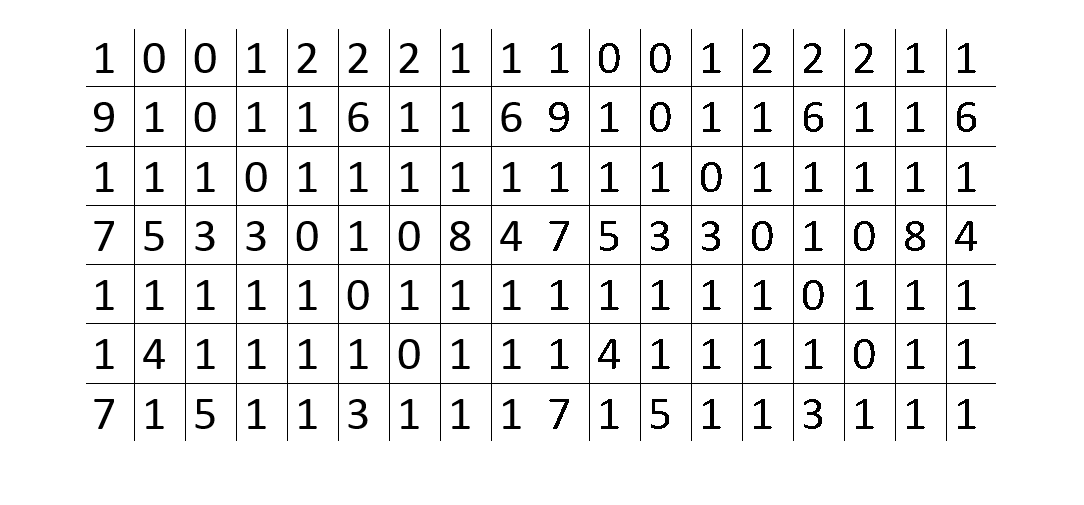

% figure; 
% imshowpair(I, BW, 'montage');

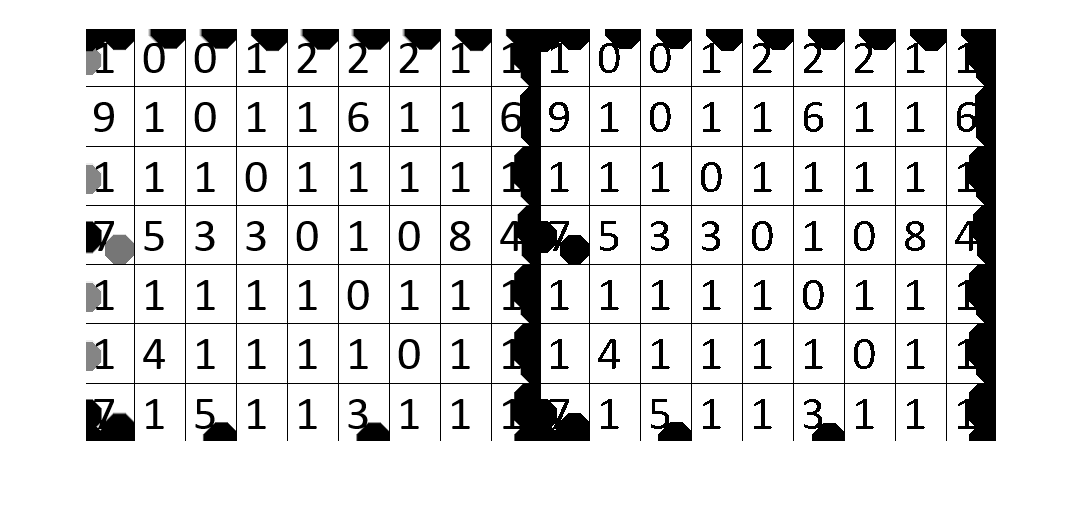

% % Remove keypad background
% Icorrected = imtophat(I, strel('disk', 15));
% 
% BW1 = imbinarize(Icorrected);
% 
% figure; 
% imshowpair(Icorrected, BW1, 'montage');

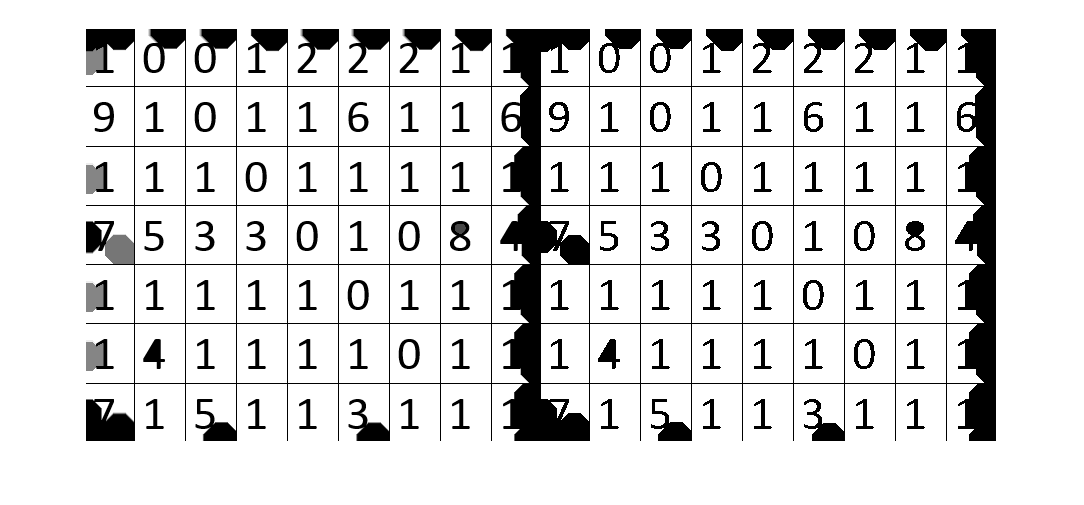

% % Perform morphological reconstruction and show binarized image.
% marker = imerode(Icorrected, strel('line',10,0));
% Iclean = imreconstruct(marker, Icorrected);
% 
% BW2 = imbinarize(Iclean);
% 
% figure; 
% imshowpair(Iclean, BW2, 'montage');

% % Perform morphological reconstruction and show binarized image.
% marker = imerode(Icorrected, strel('line',10,0));
% Iclean = imreconstruct(marker, Icorrected);
% 
% BW2 = imbinarize(Iclean);
% 
% figure; 
% imshowpair(Iclean, BW2, 'montage');

% 
% results = ocr(BW2, 'CharacterSet', '0123456789', 'TextLayout','Block');
% 
% pppp = results.Text

pppp =     '0 0
     
     9 1135
     1 111
     1 111135
     1 111
     1 5111
     1 1 1 1 1 1
     
     '


% 
% 
% % The regular expression, '\d', matches the location of any digit in the
% % recognized text and ignores all non-digit characters.
% regularExpr = '\d';
% 
% % Get bounding boxes around text that matches the regular expression
% bboxes = locateText(results, regularExpr, 'UseRegexp', true);
% 
% digits = regexp(results.Text, regularExpr, 'match');
% 
% % draw boxes around the digits
% Idigits = insertObjectAnnotation(I, 'rectangle', bboxes, digits);
% % Use the 'CharacterSet' parameter to constrain OCR
% results = ocr(BW2, 'CharacterSet', '0123456789', 'TextLayout','Block');
% 
% results.Text

ans =     '0 0
     
     9 1135
     1 111
     1 111135
     1 111
     1 5111
     1 1 1 1 1 1
     
     '


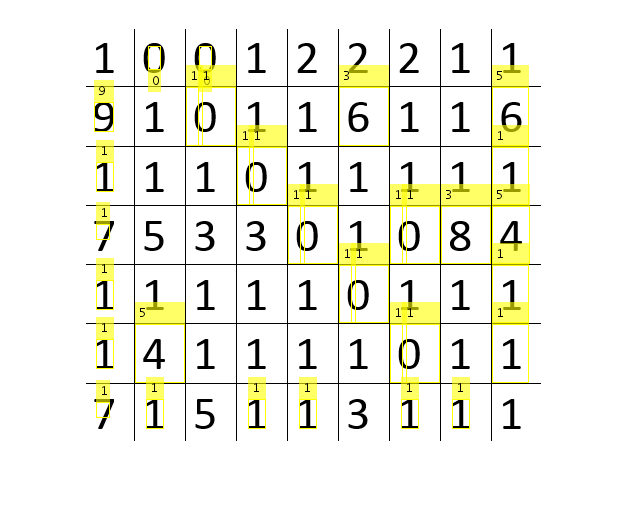

% figure; 
% imshow(Idigits);